# Predict Battery Temperature Using Neural Networks

Copyright 2023 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('ElectricVehicleDesignOverview.html')).

This example shows how to generate data for training a neural network for battery temperature estimation, and how to generate a C-code for deployment on the hardware. To model the battery temperature, this example uses neural networks based on the training data from a detailed battery physics (Simscape™) model. To ascertain the prediction accuracy, the example then verifies the trained neural network with a different current profile.

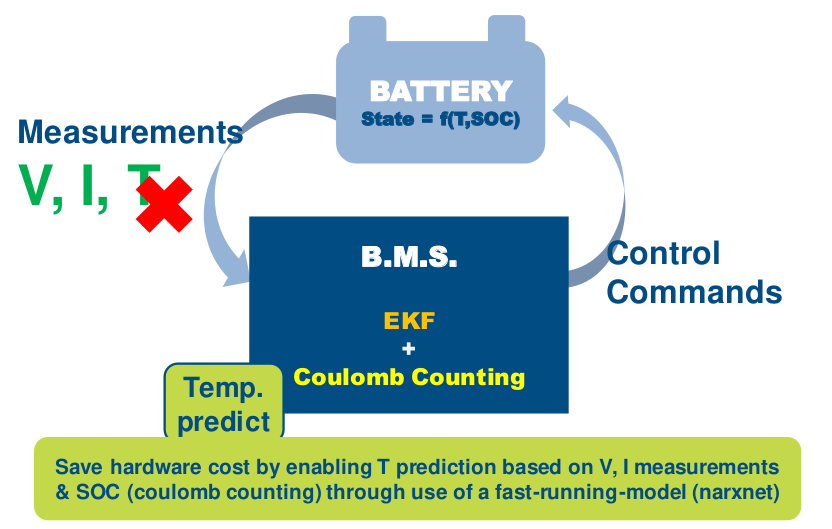

In an automotive battery pack, the pack voltage, current, and temperature sensors send measurement signals to the battery management system (BMS). These signals are important for the battery control and the logic implementation. Due to the high cost and the difficulty of installing sensors in large battery packs, a numerical method to estimate the battery temperature helps replacing or complementing the sensors in case of any failure or malfunctioning. This enables cost savings by eliminating the need of a thermocouple and an onboard numerical estimation of the battery temperature based on the voltage and current sensor measurements.

## Define Model Structure

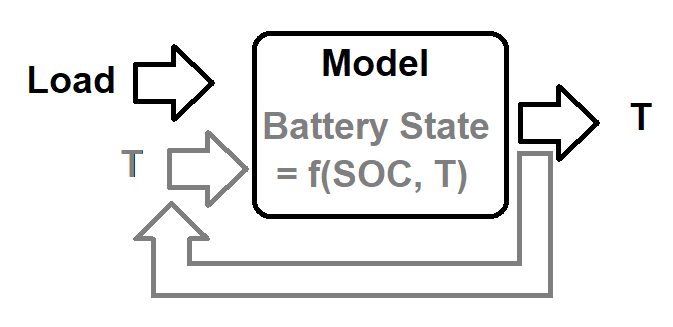

Use the state of charge (SOC) and temperature to define the state of the battery. To predict the future temperature profile of the battery, you must study the load applied on the battery pack and possess some information on its temperature state. To obtain this information, use the product of the battery instantaneous current and voltages as its load. You can predict the future temperatures by knowing only a few initial states of the battery temperature. NARX models are well suited for such applications. This examples shows you how to define a NARX model with a temperature delay in multiple timesteps during the training.

## Gather Data For Training

To generate the training data for the neural network, this example uses a detailed physics-based model for the battery pack. If you have real hardware data available, you do not require this physics-based simulation.

To generate data to train the model, open the model `BatteryTestHarness`. 

open_system('BatteryTestHarness')

Set the environment temperature to 300K, the coolant temperature to 300K, and the coolant flowrate to 0.05 kg/s.

temperatureEnv  = 300;
temperatureCool = 300;
flowrateCool    = 0.05;

Define the coolant and environment parameters in the `BatteryTestHarness` model.

set_param('BatteryTestHarness/Reservoir (TL)',...
    'reservoir_temperature', num2str(temperatureCool));
set_param('BatteryTestHarness/Reservoir (TL)1',...
    'reservoir_temperature', num2str(temperatureCool));
set_param('BatteryTestHarness/Mass Flow Rate Source (TL)',...
    'commanded_mass_flow',num2str(flowrateCool));

To generate synthetic training data, set the parameters to different discharge-charge rates. This example uses three different C rates to generate the training data: 0.5 C rate (~50.5A current), 1C rate (~101A current), and 1.5C rate (~151.5A current). To generate the data, run a sequence of increasing constant discharge-charge currents, followed by a decreasing sequence of constant discharge-charge currents. A long resting period separates the two events. This ensures that you capture all the relevant C rates, temperature points, and the SOC points of interest for the final deployment application.

Define the training profile.

% DATA FORMAT [t_start, t_end, <current_value>; ...
%              t_start, t_end, <current_value>; ...] and so on...
trainingProfile = [0 7100 50.5; ...       % 0.5C discharge
                   7101 14200 -50.5; ...  % 0.5C charge
                   14201 17750 101; ...   % 1C discharge
                   17751 21350 -101; ...  % 1C charge
                   21351 23750 151.5; ... % 1.5C discharge
                   23751 26150 -151.5; ...% 1.5C charge
                   26151 28000 0; ...     % REST
                   28001 30400 151.5; ... % 1.5C discharge
                   30401 32800 -151.5; ...% 1.5C charge
                   32801 36351 101; ...   % 1C discharge
                   36352 39950 -101; ...  % 1C charge
                   39951 47150 50.5; ...  % 0.5C discharge
                   47151 54351 -50.5; ... % 0.5C charge
                   54352 56000 0];        % REST
inpTrainingProfile = strcat(mat2str(trainingProfile),'|0.1');
endTime = num2str(trainingProfile(end,2));

Define the model parameters.

set_param('BatteryTestHarness','StopTime',endTime);
set_param('BatteryTestHarness/Inputs/Load current',...
    'MaskValueString',inpTrainingProfile);
setRelayData = strcat('[',num2str([0, trainingProfile(end,2), 1]),']|0.1');
set_param('BatteryTestHarness/Inputs/Pos Relay Cmd',...
    'MaskValueString',setRelayData);
set_param('BatteryTestHarness/Inputs/Neg Relay Cmd',...
    'MaskValueString',setRelayData);

Set the battery parameters, the initial SOC, and the ambient temperature.

run('BatteryTestHarnessParam')
battery.initialPackSOC = 1;
vehicleThermal.ambient = temperatureEnv;
run('batt_BatteryManagementSystem_param'); 
run('batt_packBTMSExampleLib_param');warning('off','all');

Run the test harness and store the data in the `battSensorData` variable.

battSim = sim('BatteryTestHarness');
bdclose('BatteryTestHarness')
battSensorData = battSim.logsout.extractTimetable;

Extract the relevant battery data and save in a struct named `training`. The function `BatteryNeuralNetSimRes` defines the struct `training` and the time step, training.tsNeuralNetSet, for the neural network training. In this example, `training.tsNeuralNetSet `is set to one second.

training = BatteryNeuralNetSimRes(1, battSensorData);

Plot the current and voltage profiles to visualize the training data.

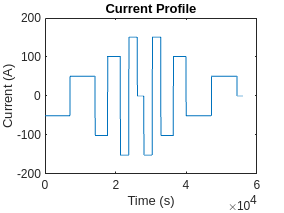

figure("Name","Current Profile For Training")
plot(training.time, training.current);
title('Current Profile');
xlabel('Time (s)'); ylabel('Current (A)');

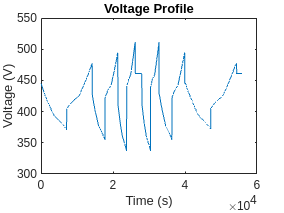


figure("Name","Voltage Profile For Training")
plot(training.time, training.voltage);
title('Voltage Profile');
xlabel('Time (s)'); ylabel('Voltage (V)');

Plot the battery temperature profile for the training data.

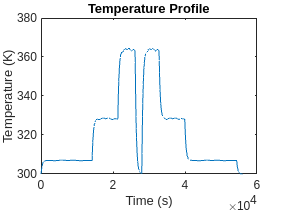

figure("Name","Temperature Profile For Training")
plot(training.time, training.temperature);
title('Temperature Profile');
xlabel('Time (s)'); ylabel('Temperature (K)');

## Train Neural Network

You must first normalize the training data, before using it to train the model. You must then set up the training parameters and define a suitable values for the hidden layer size and the delay time steps. For more information, see [Design Time-Series NARX Feedback Neural Networks](https://www.mathworks.com/help/deeplearning/ug/design-time-series-narx-feedback-neural-networks.html).

### Normalize Training Data

The `dataPow`, `dataSOC`, and `dataTmp` fields of the `training` struct define the input data for model training. The temperature data, `dataTmp`, is the temperature relative to the coolant inlet temperature (and the ambient temperature) and it is equal to 300K.

training.dataPow = (training.current.*training.voltage)';
training.dataSOC = training.stateOfCharge';
training.dataTmp = (training.temperature - vehicleThermal.ambient)';

Normalize the temperature data, `training.dataTmp`.

% Normalize output data, Temperature T
training.mu_tmp  = mean(training.dataTmp,1);
training.sig_tmp = std(training.dataTmp,0,1);
training.dataTmp = (training.dataTmp-training.mu_tmp)/training.sig_tmp;

Normalize the power data, `training.dataPow`.

% Normalize input data for Power, P
training.mu_pow  = mean(training.dataPow,1);
training.sig_pow = std(training.dataPow,0,1);
training.dataPow = (training.dataPow-training.mu_pow)/training.sig_pow;

The SOC values are between 0 and 1 and do not require any normalization.

### Set Training Parameters

Convert the training data to cell arrays.

training.data_NARX_Y     = training.dataTmp';
training.data_NARX_X2    = [training.dataPow';training.dataSOC'];
training.cellArrayNARX_X = con2seq(training.data_NARX_X2);
training.cellArrayNARX_Y = con2seq(training.data_NARX_Y);

Define a cell array `trainedNet` to store the trained network, training errors, and the parameters used for the training-data normalization.

trainedNet = cell(3,1);

Define the hidden layer size and the number of delay time-steps.

training.delaySteps      = 3;
training.hiddenLayerSize = 5;
training.trainFcn        = 'trainlm'; % Optimization Algorithm.
training.inputDelays     = 1:training.delaySteps;
training.feedbackDelays  = 1:training.delaySteps;

Set the network parameters.

training.narx_net = narxnet(training.inputDelays,...
                            training.feedbackDelays,...
                            training.hiddenLayerSize, ...
                            'open',training.trainFcn);
training.narx_net.trainParam.min_grad = 1e-6;
[training.p,training.Pi,training.Ai,training.t] = ...
    preparets(training.narx_net,training.cellArrayNARX_X,{},training.cellArrayNARX_Y);

Divide the training data set into train, validate, and test data sets in a ratio of 80/10/10 percentage, respectively.

training.narx_net.divideParam.trainRatio = 80/100;
training.narx_net.divideParam.valRatio   = 10/100;
training.narx_net.divideParam.testRatio  = 10/100;

### Train Model

Train the model for NARX open loop.

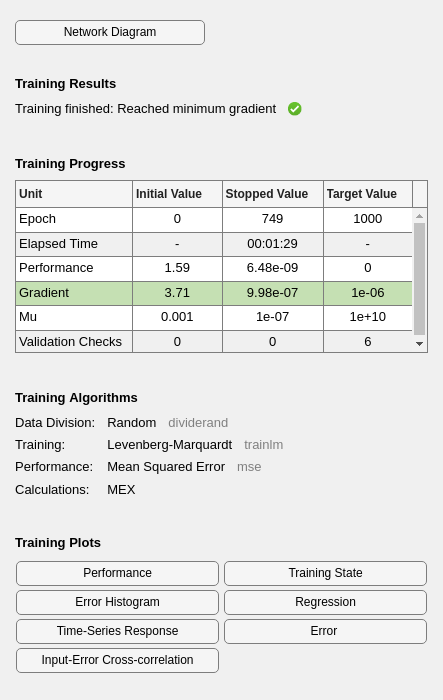

training.narx_net        = train(training.narx_net,training.p,training.t,training.Pi);

training.yp              = sim(training.narx_net,training.p,training.Pi);
training.errOpenLoop     = cell2mat(training.yp)-cell2mat(training.t);

Convert the model to closed loop.

training.narx_net_closed = closeloop(training.narx_net);
[training.p,training.Pi,training.Ai,training.t] = ...
    preparets(training.narx_net_closed,training.cellArrayNARX_X,{},training.cellArrayNARX_Y);
training.yp              = training.narx_net_closed(training.p,training.Pi,training.Ai);
training.errClosedLoop   = ((cell2mat(training.t)-cell2mat(training.yp)).*...
                           training.sig_tmp + training.mu_tmp);

Save the trained network, training errors, and the parameters used for the training-data normalization.

trainedNet{3,1} = [training.mu_tmp,training.sig_tmp,training.mu_pow,training.sig_pow,vehicleThermal.ambient]; 
trainedNet{2,1} = [training.errOpenLoop,training.errClosedLoop]; 
trainedNet{1,1} = training.narx_net_closed;

In this example, the hidden layer size is equal to 20 based on some runs carried out with different hidden layer sizes. To select the appropriate hidden layer, open and closed loop errors were used as an indication of the fit. With a modeling timestep of 1s and a delay of 3s, the temperature feedback of the last 3s was sufficient to obtain a good trained model. To achieve faster training and an approximate fit, the `training.narx_net.trainParam.min_grad` parameter is set to 1e-6. This example uses  the default training function, [Levenberg-Marquardt](https://www.mathworks.com/help/deeplearning/ref/trainlm.html), for training. For more information about training functions, see [Choose a Multi-Layer Neural Network Training Function](https://www.mathworks.com/help/deeplearning/ug/choose-a-multilayer-neural-network-training-function.html).

### Verify Model

thisTraining  = BatteryNeuralNetVerify(trainedNet{1,1},training.cellArrayNARX_X,training.cellArrayNARX_Y);

Load the pre-trained model.

preTrainedMdl = load('BatteryNeuralNetModelPreTrained.mat');
savedTraining = BatteryNeuralNetVerify(preTrainedMdl.trainedNet{1,1},training.cellArrayNARX_X,training.cellArrayNARX_Y);

Find the neural network prediction from this training and the pre-trained model.

thisTemp = cell2mat(thisTraining).*trainedNet{3,1}(1,2) + trainedNet{3,1}(1,1) + trainedNet{3,1}(1,5);
bestTemp = cell2mat(savedTraining).*preTrainedMdl.trainedNet{3,1}(1,2) + preTrainedMdl.trainedNet{3,1}(1,1) + preTrainedMdl.trainedNet{3,1}(1,5);

Add a delay time step temperature to the model.

thisTemp = [ones(1,trainedNet{1,1}.numInputDelays)*trainedNet{3,1}(1,5),thisTemp];
bestTemp = [ones(1,preTrainedMdl.trainedNet{1,1}.numInputDelays)*preTrainedMdl.trainedNet{3,1}(1,5),bestTemp];

Plot the results of training and compare the with this pre-trained model.

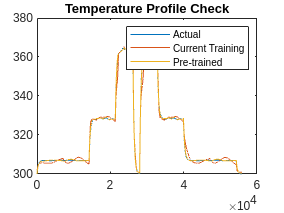

figure("Name","Neural Net Verification")
plot(training.time, training.temperature);
hold on
plot(training.time, thisTemp);
hold on
plot(training.time, bestTemp);
hold off
title('Temperature Profile Check');
legend('Actual','Current Training','Pre-trained')

Once you obtain the desired fit, save the trained model.

## Test Drive Profiles

Use the trained network, predict a completely different power demand, and compare the temperature predictions between the neural network and the battery plant model. This example uses a pre-trained model to predict battery temperature under different current profile scenarios. 

Load the pre-trained model.

load('BatteryNeuralNetModelPreTrained.mat');
nDel        = trainedNet{1,1}.numInputDelays;
useNetwork  = trainedNet{1,1};
mu_tmp      = trainedNet{3,1}(1,1);
sig_tmp     = trainedNet{3,1}(1,2);
mu_pow      = trainedNet{3,1}(1,3);
sig_pow     = trainedNet{3,1}(1,4);
tempRef     = trainedNet{3,1}(1,5);

Open the battery model and set parameters used during training.

open_system('BatteryTestHarness');
set_param('BatteryTestHarness/Reservoir (TL)',...
    'reservoir_temperature', num2str(temperatureCool));
set_param('BatteryTestHarness/Reservoir (TL)1',...
    'reservoir_temperature', num2str(temperatureCool));
set_param('BatteryTestHarness/Mass Flow Rate Source (TL)',...
    'commanded_mass_flow',num2str(flowrateCool));

Define a current profile.

drv = load('BatteryNeuralNetDriveProfile01.mat');
endTime = num2str(drv.driveProfile(end,2));
set_param('BatteryTestHarness','StopTime',endTime);
inpDriveProfile = strcat(mat2str(drv.driveProfile),'|0.1');
set_param('BatteryTestHarness/Inputs/Load current',...
    'MaskValueString',inpDriveProfile);
setRelayData = strcat('[',num2str([0, drv.driveProfile(end,2), 1]),']|0.1');
set_param('BatteryTestHarness/Inputs/Pos Relay Cmd',...
    'MaskValueString',setRelayData);
set_param('BatteryTestHarness/Inputs/Neg Relay Cmd',...
    'MaskValueString',setRelayData);

Initialize the battery parameters.

run('BatteryTestHarnessParam');
battery.initialPackSOC = 1;
vehicleThermal.ambient = temperatureEnv;
run('batt_BatteryManagementSystem_param'); 
run('batt_packBTMSExampleLib_param');

Run the battery model and save the data.

battSim = sim('BatteryTestHarness');
bdclose('BatteryTestHarness')
battSensorData = battSim.logsout.extractTimetable;
data = BatteryNeuralNetSimRes(1, battSensorData);

Plot the current profile.

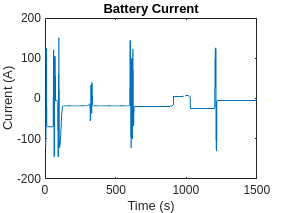

figure("Name","Battery Current Profile")
plot(data.time,data.current);
title('Battery Current');
xlabel('Time (s)');ylabel('Current (A)');

Prepare the data to provide as input to the neural network.

predictTemp           = zeros(1,length(data.temperature));
predictTemp(1,1:nDel) = vehicleThermal.ambient;

verify_NARX_Y   = (predictTemp-tempRef-mu_tmp)/mu_tmp;
inputNNX1       = (data.current.*data.voltage-mu_pow)./sig_pow;
verify_NARX_X2  = [inputNNX1;data.stateOfCharge];
verifyNARX_X    = con2seq(verify_NARX_X2);
verifyNARX_Y    = con2seq(verify_NARX_Y);

Predict the battery temperature.

battTemp = BatteryNeuralNetVerify(useNetwork,verifyNARX_X,verifyNARX_Y);

Convert the temperature output from the neural network to an appropriate form.

predictTemp(1,nDel+1:end) = cell2mat(battTemp).*sig_tmp+mu_tmp+tempRef;

Plot the results.

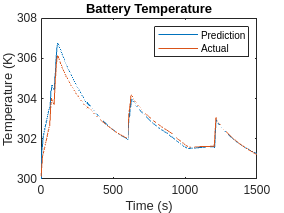

figure("Name","Battery Temperature Prediction")
plot(data.time,predictTemp);
hold on
plot(data.time,data.temperature);
hold off
legend('Prediction','Actual');
title('Battery Temperature');
xlabel('Time (s)');ylabel('Temperature (K)');

## Generate C Code

### Create MATLAB Function

TpredFunc              = zeros(1,length(data.temperature));
TpredFunc(1,1:nDel)    = vehicleThermal.ambient;
TpredCodeGen           = zeros(1,length(data.temperature));
TpredCodeGen(1,1:nDel) = vehicleThermal.ambient;

To generate the C code from the neural network, use the `genFunction` function. 

genFunction(useNetwork,'BatteryNeuralNetNARX','MatrixOnly','yes');

 
MATLAB function generated: BatteryNeuralNetNARX.m
To view generated function code: edit BatteryNeuralNetNARX
For examples of using function: help BatteryNeuralNetNARX
 


[p,Pi,Ai,~] = preparets(useNetwork,verifyNARX_X,{},verifyNARX_Y);
mat_p=cell2mat(p);   % Convert cell arrays to matrix
mat_Pi=cell2mat(Pi);
mat_Ai=cell2mat(Ai);
% Find temperature prediction
calcTpredFunc           = BatteryNeuralNetNARX(mat_p,mat_Pi,mat_Ai(end,:));
TpredFunc(1,nDel+1:end) = calcTpredFunc.*sig_tmp+mu_tmp+tempRef;

Then, use **codegen** to generate the desired C code.

mat_p_type  = coder.typeof(double(0),[2,inf]);
mat_Pi_type = coder.typeof(double(0),[2,3]);
mat_Ai_type = coder.typeof(double(0),[1,3]);
codegen BatteryNeuralNetNARX.m -config:mex -o BatteryNeuralNetCodeGen -args {mat_p_type,mat_Pi_type,mat_Ai_type}

Code generation successful.



calcTpredCodeGen           = BatteryNeuralNetCodeGen(mat_p,mat_Pi,mat_Ai(end,:));
TpredCodeGen(1,nDel+1:end) = calcTpredCodeGen.*sig_tmp+mu_tmp+tempRef;

To visualize the performance of the MATLAB® function and the generated C code, at the MATLAB Command Window, enter:

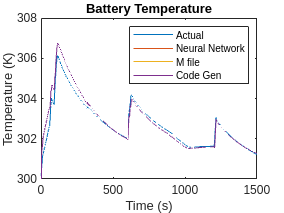

figure("Name","Model Deployment")
plot(data.time,data.temperature);
hold on
plot(data.time,predictTemp);
hold on
plot(data.time,TpredFunc);
hold on
plot(data.time,TpredCodeGen);
hold off
legend('Actual','Neural Network','M file','Code Gen');
title('Battery Temperature');
xlabel('Time (s)');ylabel('Temperature (K)');

### Deploy On Hardware

To generate a Simulink® block diagram of a neural network, use the function **gensim**

gensim(trainedNet{1,1});

The generated Simulink model has been tested on a Speedgoat Performance real-time target machine with an Intel(R) 3.5 GHz i7 multi-core CPU. For more information on hardware deployment, see [Creating and Running Real-Time Applications | R2020b Tutorials ? Speedgoat](https://www.speedgoat.com/knowledge-center/simulink-real-time-basics/r2020b-slrt-part-3).